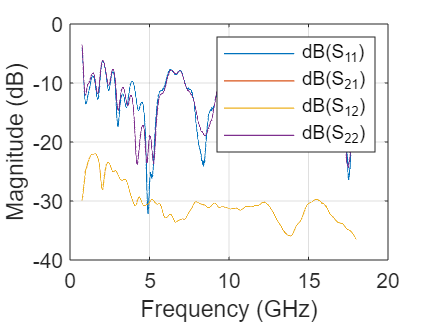

% Function:    Touch-stone file to csv with a linear interpolation 0.1MHz step
% Description: Convert Touchstone to CSV with the interpolation. Adding 0.1MHz step points.

clear;
close all;
clc;
sympref('FloatingPointOutput',false);
sympref('AbbreviateOutput',true);
format LongEng;

output_dir = '../output/';
sp_file='../input_cal/Measurement_Site_19_KIT/20221126_SiteCal_ETS3115_HornBothSide.s2p';
%sp_file_name = split(sp_file,'.');
[sp_file_path, sp_file_name,] = fileparts(sp_file);
sp_ref = sparameters(sp_file);

sp_freq= sp_ref.Frequencies; % Hz
sp_freq_MHz = sp_freq/1e6;
sp_freq_MHz_new_points = sp_freq_MHz(1):0.1:sp_freq_MHz(end);   % sample to 0.1 MHz step
sp_freq_MHz_new_points = transpose(sp_freq_MHz_new_points);
sp_freq_MHz_interp = [sp_freq_MHz; sp_freq_MHz_new_points];

sp_freq_MHz_interp = sort(sp_freq_MHz_interp);
sp_s11_dB = 20*log10(abs(rfparam(sp_ref,1,1)));
sp_s21_dB = 20*log10(abs(rfparam(sp_ref,2,1)));

sp_s11_dB_interp = interp1(sp_freq_MHz,sp_s11_dB,sp_freq_MHz_interp);
sp_s21_dB_interp = interp1(sp_freq_MHz,sp_s21_dB,sp_freq_MHz_interp);

data_s11 = [sp_freq_MHz_interp sp_s11_dB_interp];
filename = string(append(output_dir,sp_file_name,'_s11.csv'));
writematrix(data_s11,filename);

data_s21 = transpose([sp_freq_MHz;sp_s21_dB]);
filename = string(append(output_dir,sp_file_name,'_s21.csv'));
writematrix(data_s21,filename);

rfplot(sp_ref);

% --- Exporting to SQLite
filename_db = 'antmeas.db';
filename = append(output_dir,filename_db);
conn = sqlite(filename,"create");      % auto-commit mode

data = table(sp_freq_MHz_interp,sp_s11_dB_interp,sp_s21_dB_interp,'VariableNames',["frequency_MHz" "s11_dB" "s21_dB"]);
sqlwrite(conn, 'Site_Measurement', data);

close(conn);

% conn = sqlite(filename);      % auto-commit mode
% readdb = sqlread(conn,'Site_Measurement');
% close(conn);
% plot(readdb.frequency_MHz,readdb.s11_dB,readdb.frequency_MHz,readdb.s21_dB);